# 声学工具箱使用

## kraken使用：

clc;clear;
kraken testEnvs\MunkK;

___________________________________________________________________________
Running field.m
/,				! TITLE
RA
MLimit = 9999 


_______________________ 

 Number of profiles, NProf = 1 

 Profile ranges, rProf (km) 
    0.00  

_______________________ 

 Number of receiver ranges, NRr = 1001 

 Receiver ranges, Rr (km) 
    0.00 ...   100.00 

_______________________ 

 Number of source   depths, NSz   = 1 

 Source depths, Sz (m)
 1000.00 

_______________________ 

 Number of receiver depths, NRz   = 501 

 Receiver depths, Rz (m)
    0.00 ...  5000.00 

_______________________ 

 Number of receiver range offsets (array tilt) = 501 

 Receiver range offsets, R.ro (m)
    0.00 ...     0.00 
  



绘制传播损失

%传播损失
global units;
units = 'km';%这样输出单位为km
figure;
plotshd testEnvs\MunkK.shd.mat;%此处注意添加.mat

错误使用 load
找不到文件或目录 'testEnvs\MunkB_Coh.shd.mat'。

出错 read_shd (第 85 行)
      load( filename )

出错 plotshd (第 24 行)
      [ PlotTitle, ~, freqVec, ~, ~, Pos, pressure ] = read_shd( filename );

绘制随深度变化的传播损失

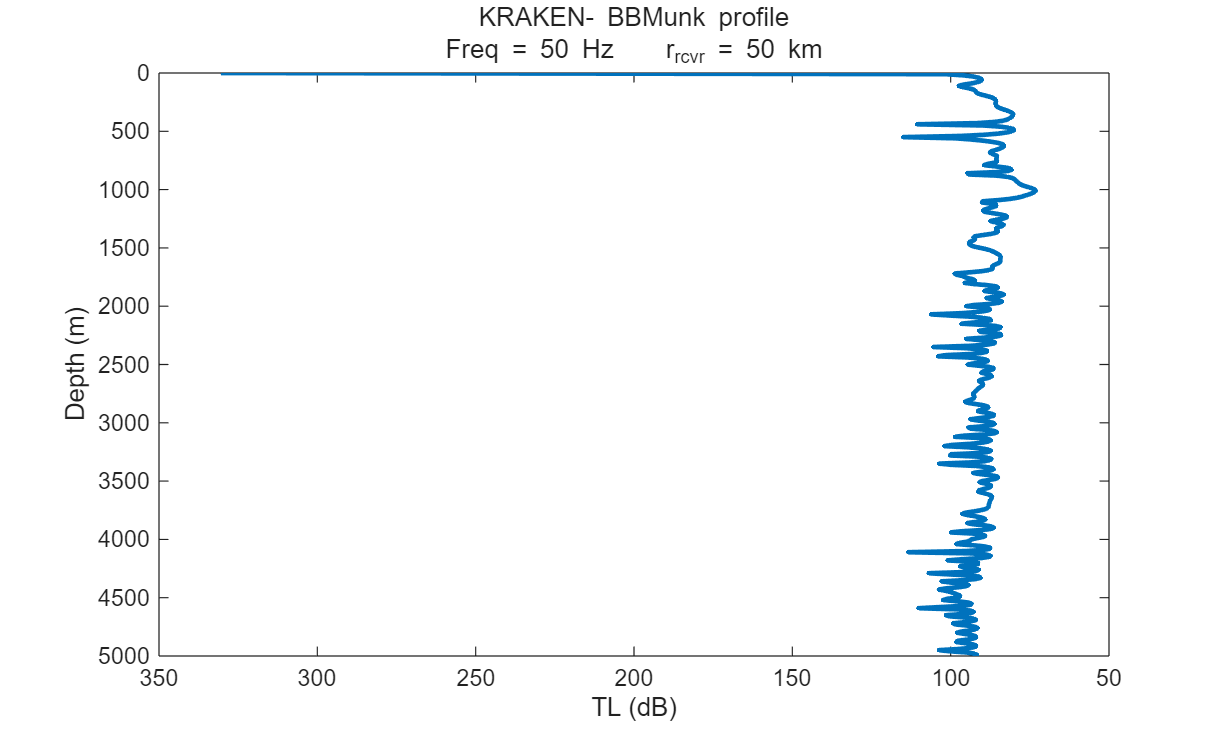

PlotTLd uses the first bearing and source depth in the shade file; check OK


figure;
plottld('testEnvs\MunkK.shd.mat',50);%50km处随深度变化的传播损失

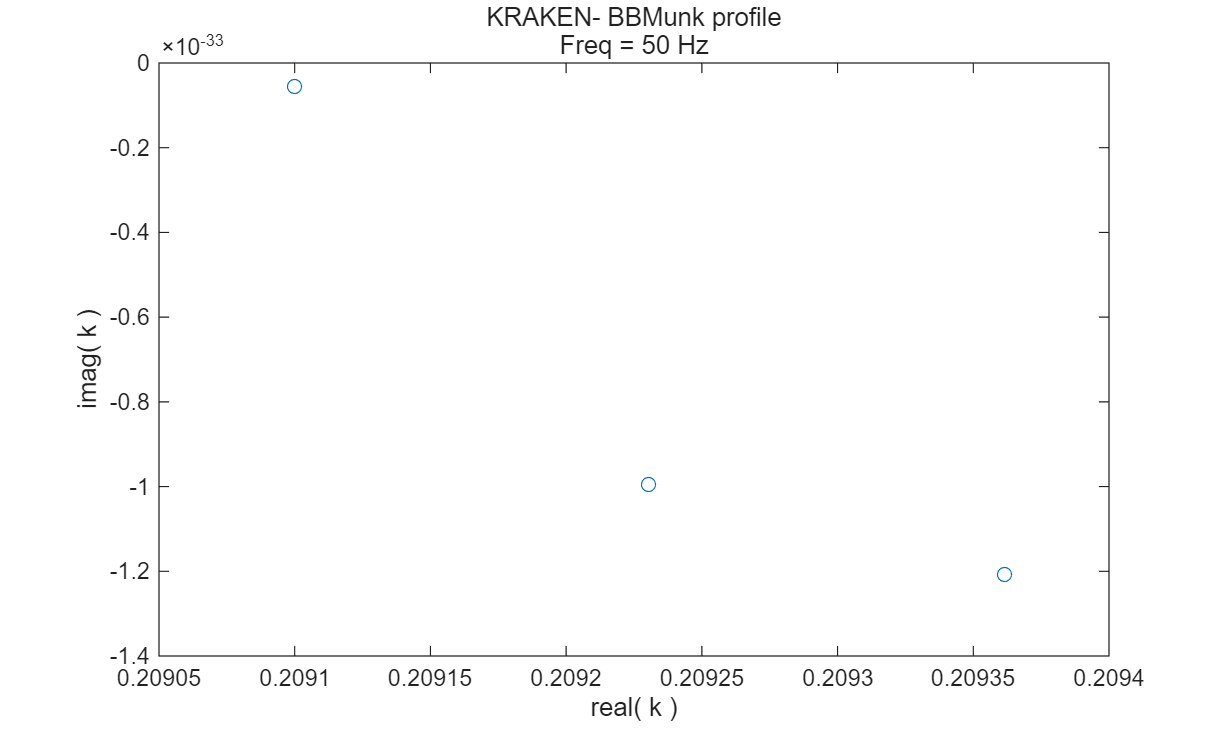

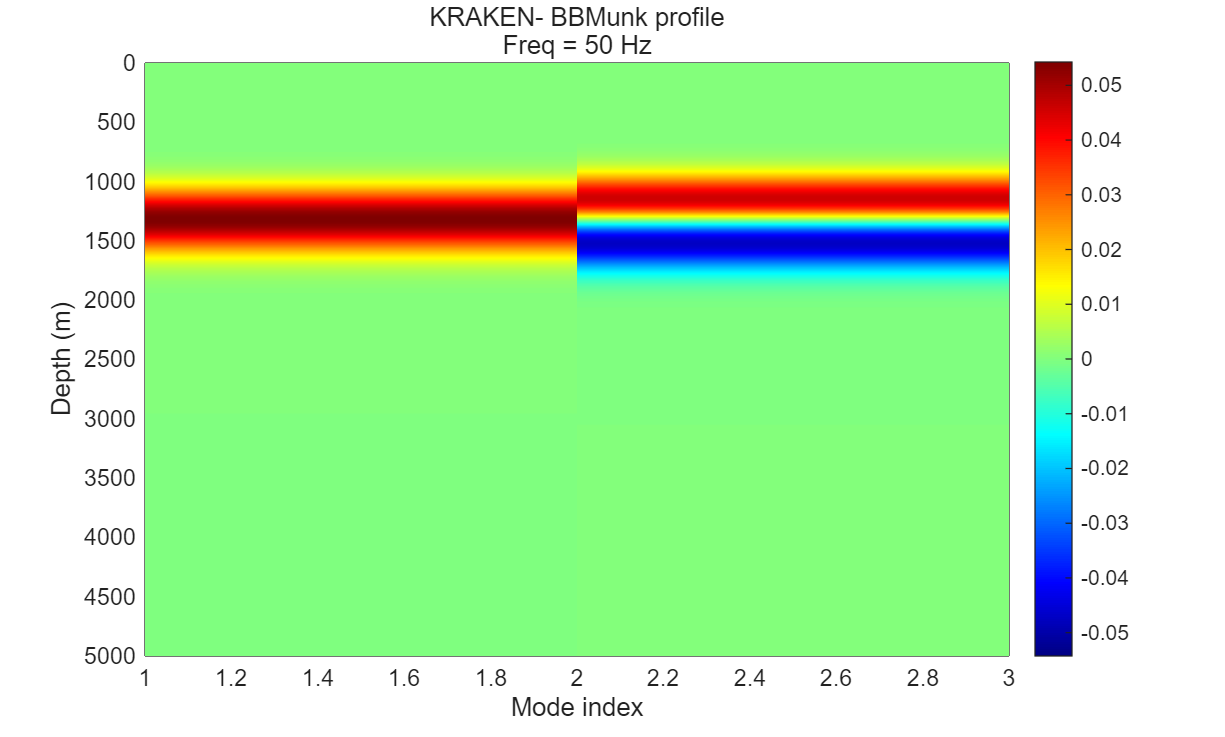

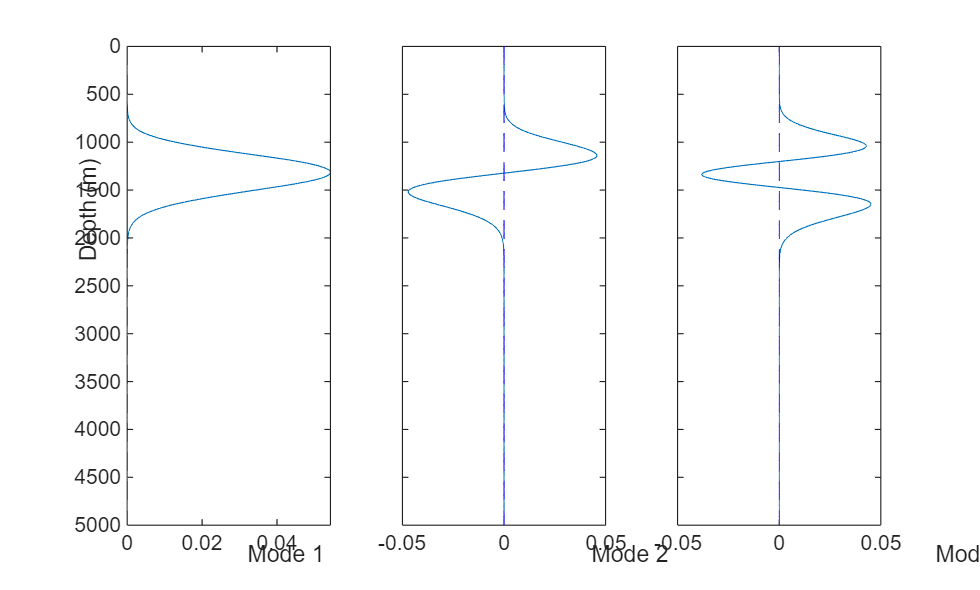

figure
plotmode('testEnvs\MunkK.mod',0,[1  2  3]);

如何读取声场

[ PlotTitle, PlotType, freqVec, freq0, atten, Pos, pressure ] = read_shd( 'testEnvs\MunkK.shd.mat' );
%load(MunkK.shd.mat);


用代码编写环境文件

[ TitleEnv, freq, SSP, Bdry, Pos, Beam, cInt, RMax, fid ] = read_env('testEnvs\MunkK.env','KRAKEN');

__________________________________________________________________
BBMunk profile
Frequency = 50 Hz 
Number of media = 1 

    N2-Linear approximation to SSP
    Attenuation units: dB/wavelength
    VACUUM

     z (m)     alphaR (m/s)      betaR       rho (g/cm^3)    alphaI        betaI 
    ( Number of pts = 0  Roughness =   0.00  Depth =  5000.00 ) 
      0.00       1548.52          0.00          1.00        0.0000        0.0000 
    200.00       1530.29          0.00          1.00        0.0000        0.0000 
    250.00       1526.69          0.00          1.00        0.0000        0.0000 
    400.00       1517.78          0.00          1.00        0.0000        0.0000 
    600.00       1509.49          0.00          1.00        0.0000        0.0000 
    800.00       1504.30          0.00          1.00        0.0000        0.0000 
   1000.00       1501.38          0.00          1.00        0.0000        0.0000 
   1200.00       1500.14          0.00          1.00        0.0000      

fclose all;
write_env( 'testEnvs\MunkK_writtenByMe', 'KRAKEN', TitleEnv, freq, SSP, Bdry, Pos, Beam, cInt, RMax);


## Bellhop的使用：

绘制传播损失

bellhop testEnvs\MunkB_Coh;
clc
figure
plotshd('testEnvs\MunkB_Coh.shd');

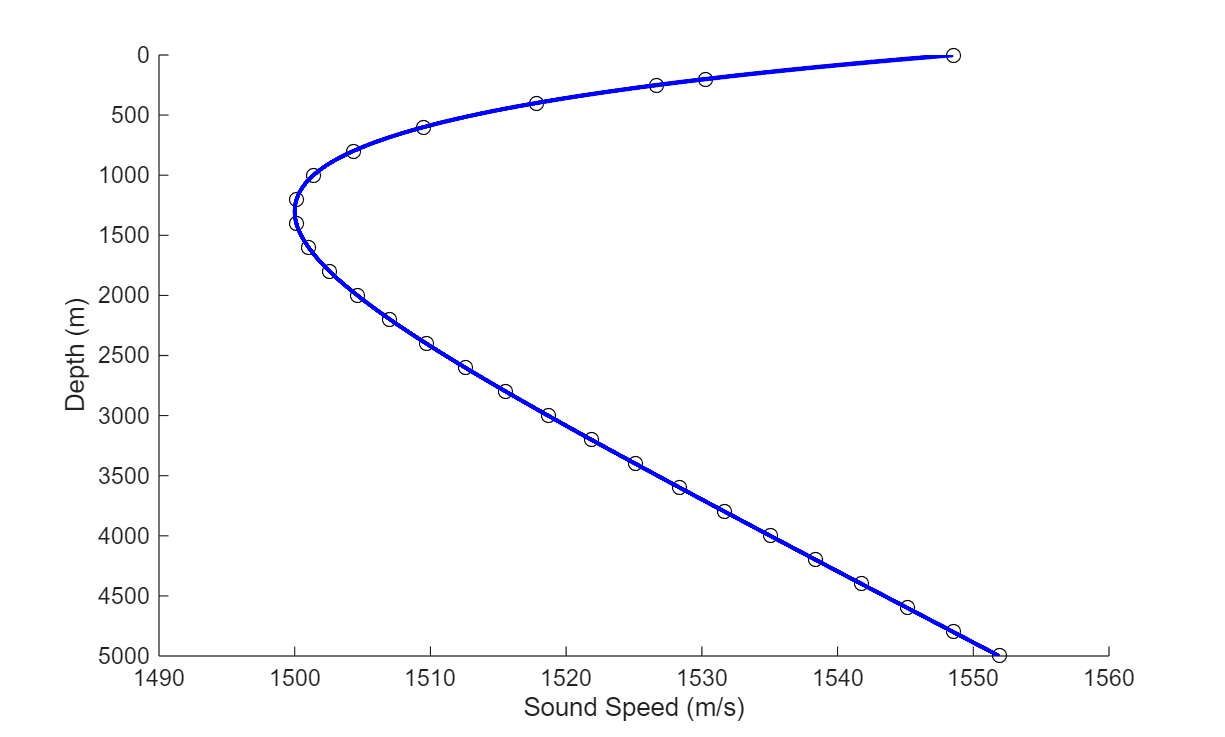

__________________________________________________________________
Munk profile, coherent
Frequency = 50 Hz 
Number of media = 1 

    Spline approximation to SSP
    Attenuation units: dB/wavelength
    VACUUM

     z (m)     alphaR (m/s)      betaR       rho (g/cm^3)    alphaI        betaI 
    ( Number of pts = 51  Roughness =   0.00  Depth =  5000.00 ) 
      0.00       1548.52          0.00          1.00        0.0000        0.0000 
    200.00       1530.29          0.00          1.00        0.0000        0.0000 
    250.00       1526.69          0.00          1.00        0.0000        0.0000 
    400.00       1517.78          0.00          1.00        0.0000        0.0000 
    600.00       1509.49          0.00          1.00        0.0000        0.0000 
    800.00       1504.30          0.00          1.00        0.0000        0.0000 
   1000.00       1501.38          0.00          1.00        0.0000        0.0000 
   1200.00       1500.14          0.00          1.00        0.0000


plotssp('testEnvs\MunkB_Coh');

bellhop arr

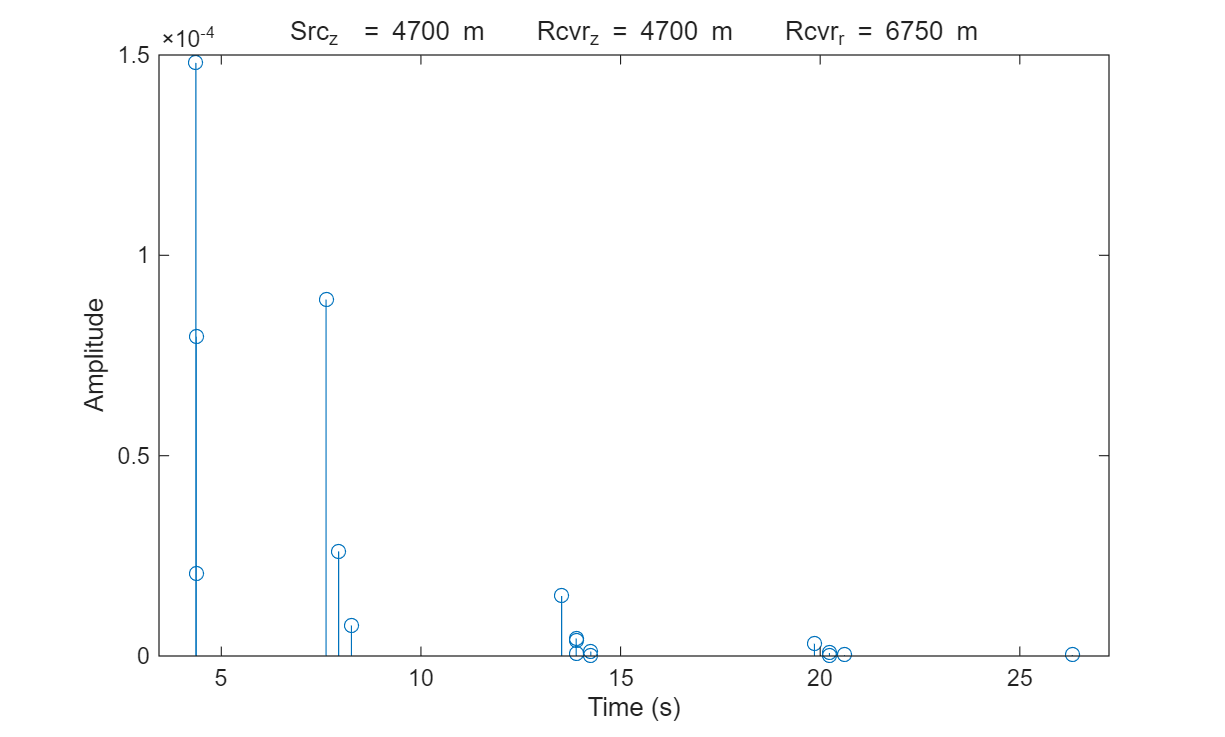

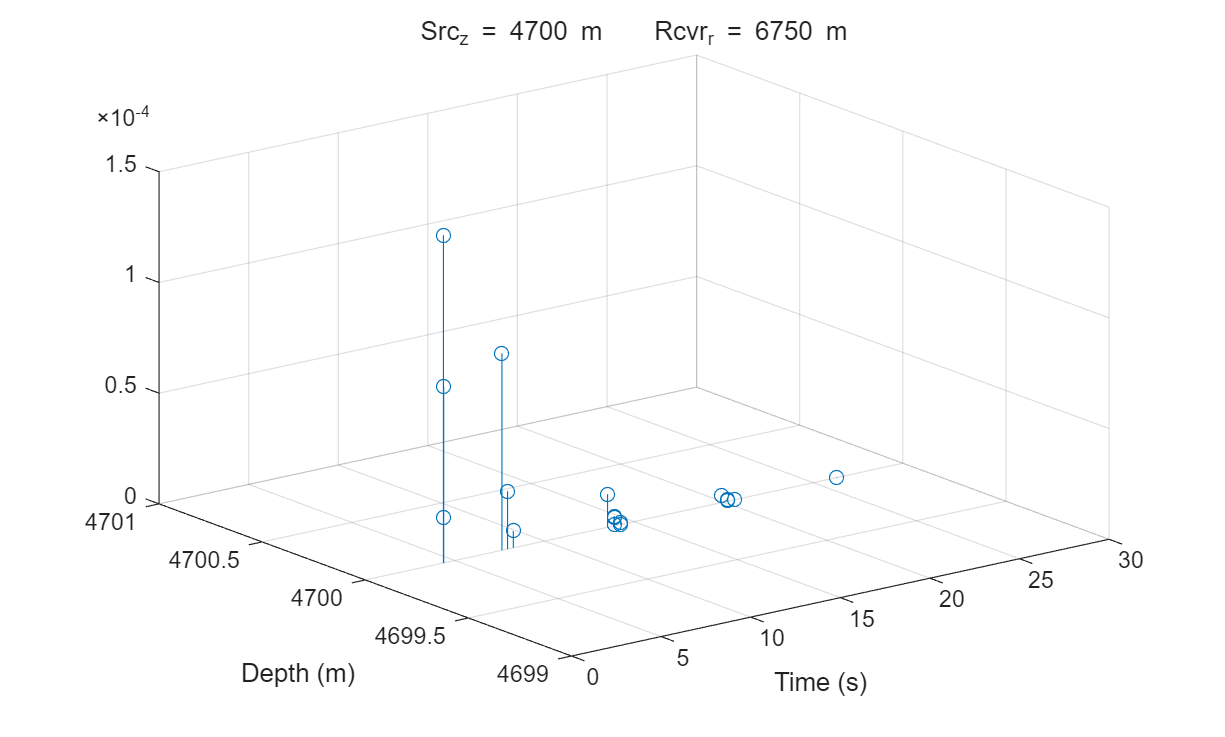

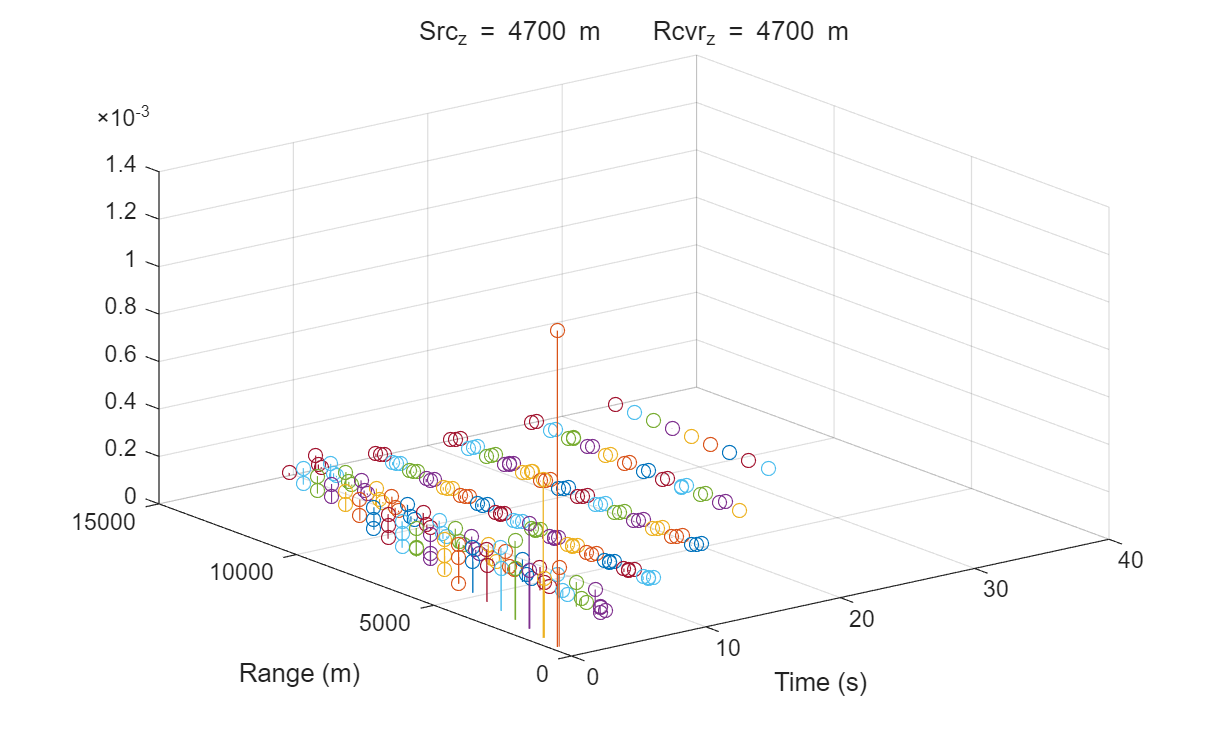

bellhop testEnvs\MunkB_Arr;
figure
plotarr('testEnvs\MunkB_Arr.arr',10,1,1);

%读取脉冲响应
filename = 'testEnvs\MunkB_Arr.arr';
Minimum_range=100;%（接收水听器的水平方向上接收范围最小值，m）----R 
Maximum_range=1000; %（接收水听器的水平方向上接收范围最大值，m）---RB 
%%单位冲激响应
[ amp1, Pos ] = read_arrivals_asc(filename);

 [m,n]=size(amp1);
 amp = abs(amp1); %取模  

Incorrect number or types of inputs or outputs for function abs.

 x = delay(m,:); %获取第50个接收机的时延和幅值
 y = amp(m,:);
 figure(1)
 stem(x,y);
 grid on;xlabel('相对时延/s');ylabel('幅度');title('单位冲激响应');


绘制声线

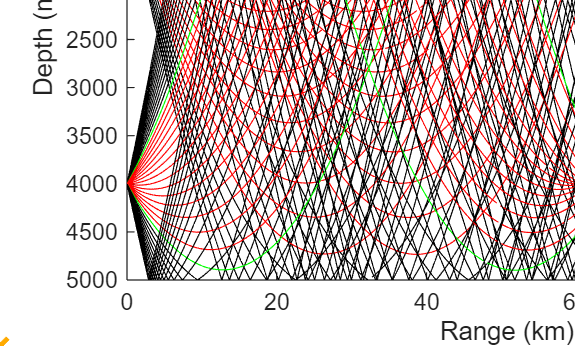


bellhop testEnvs\MunkB_ray
figure
plotray('testEnvs\MunkB_ray.ray');

本征声线

bellhop testEnvs\MunkB_EngRay;
figure
plotray('testEnvs\MunkB_EngRay.ray');